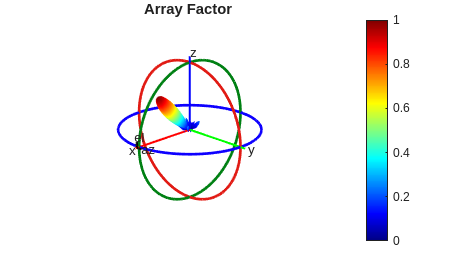

f = 1e8;
lambda = 300e6 / f;
k_0 = 2*pi/lambda;


d_theta = 1;
d_phi = 5;

theta = 0:d_theta:180;
phi = 0:d_phi:360;

[THETA ,PHI] = meshgrid(theta,phi);

THETA = deg2rad(THETA);
PHI = deg2rad(PHI); 

k_x = k_0 * sin(THETA) .* cos(PHI);  
k_y = k_0 * sin(THETA) .* sin(PHI);

AF = zeros(length(phi),length(theta));

% Size of the array
n = 6; % columns
m = 8; % rows

% Space between the elements
d_x = lambda*0.5 ;
d_y = lambda*0.5 ;


% direction
theta_0 = deg2rad(45);  
phi_0 = deg2rad(0);    
 
% steering
beta_x = -k_0 * sin(theta_0) * cos(phi_0);
beta_y = -k_0 * sin(theta_0) * sin(phi_0);


for k = 1:n
    for i = 1:m
        AF = AF + exp(1j * ((k_x + beta_x)* (i-1) * d_x + (k_y + beta_y) * (k-1) * d_y));
    end
end

%magnitude
AF_mag = abs(AF);

%boundaries to trim -z direciton
upper_bound_theta = find(theta == 90);


% trim -z direction double the other direction and normalize

AF_mag(:,upper_bound_theta:end) = 0;


AF_mag = AF_mag / max(AF_mag(:));

AF_mag_db = 20*log10(AF_mag+1e-10);
AF_mag_db(AF_mag_db < -70) = -70;

figure
patternCustom(AF_mag,theta,phi)
title("Array Factor")

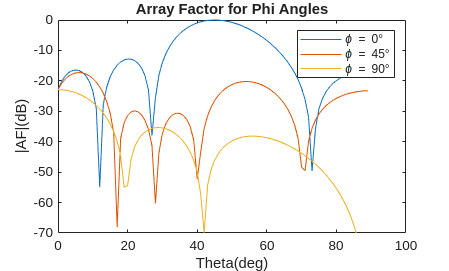

%view([0,0])

% Cut Angles
angle_1 = 0;
angle_2 = 45;
angle_3 = 90;

index_phi_1 = find(phi == angle_1);
index_phi_2 = find(phi == angle_2);
index_phi_3 = find(phi == angle_3);

figure
plot(theta,mag2db(AF_mag(index_phi_1,:)))
hold on
plot(theta,mag2db(AF_mag(index_phi_2,:)))
hold on
plot(theta,mag2db(AF_mag(index_phi_3,:)))
hold off
legend(["\phi = " + num2str(angle_1) + "°", "\phi = " + num2str(angle_2) + "°", "\phi = " + num2str(angle_3) + "°"]);
title("Array Factor for Phi Angles")
xlabel("Theta(deg)")
ylabel("|AF|(dB)")
ylim([-70 0])

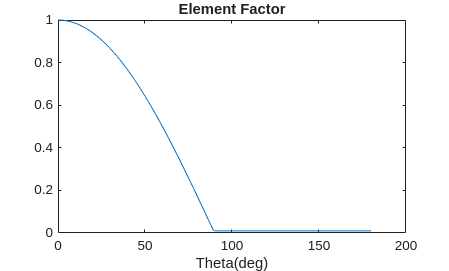


% Element Factor

ef = cos(THETA);
ef(:,upper_bound_theta:end) = 0.01;


plot(theta,ef(1,:))
title("Element Factor")
xlabel("Theta(deg)")

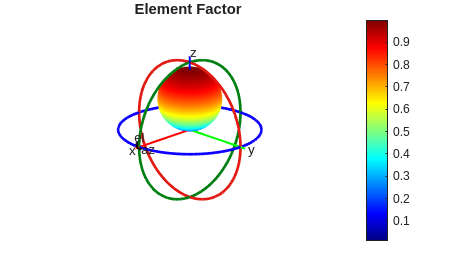



figure
patternCustom(ef,theta,phi)
title("Element Factor")

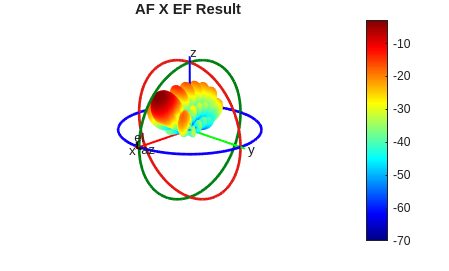





% Total
AF_total = AF_mag.*ef; 
AF_total_db = 20*log10(AF_total+1e-10);
AF_total_db(AF_total_db < -70) = -70;

figure
patternCustom(AF_total_db,theta,phi)
title("AF X EF Result")

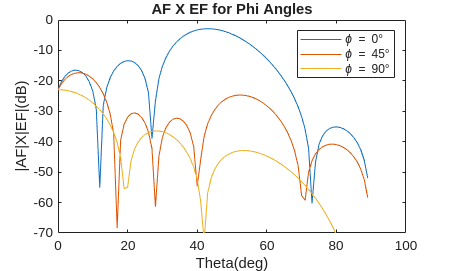


figure
plot(theta,mag2db(AF_total(index_phi_1,:)))
hold on
plot(theta,mag2db(AF_total(index_phi_2,:)))
hold on
plot(theta,mag2db(AF_total(index_phi_3,:)))
hold off
legend(["\phi = " + num2str(angle_1) + "°", "\phi = " + num2str(angle_2) + "°", "\phi = " + num2str(angle_3) + "°"]);
title("AF X EF for Phi Angles")
xlabel("Theta(deg)")
ylabel("|AF|X|EF|(dB)")
ylim([-70 0])

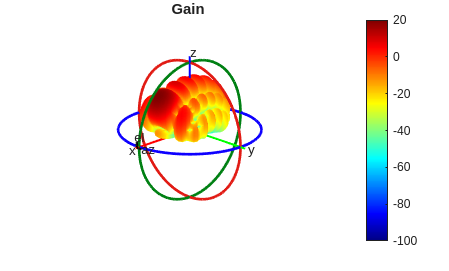



% E field and intensity of array 

E_array = AF_total;

U = abs(E_array).^2;

U(:,upper_bound_theta:end) = 0;



d_Omega = sin(THETA)*deg2rad(d_theta)*deg2rad(d_phi);
P_rad = sum(U.*d_Omega,"all");

Gain = 4*pi*U/P_rad;


Gain_db = 10*log10(Gain+1e-10);
%Gain_db(Gain_db < -150) = -150;

figure
patternCustom(Gain_db,theta,phi)
title("Gain")

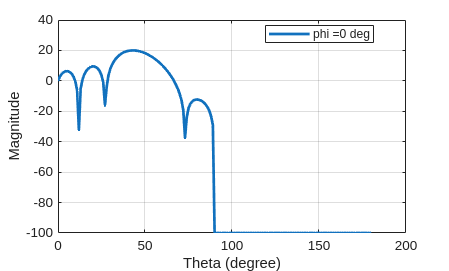



patternCustom(Gain_db, theta, phi, CoordinateSystem="rectangular",Slice="phi", SliceValue=0);


% figure
% plot(theta,mag2db(Gain_db(index_phi_1,:)))
% hold on
% plot(theta,mag2db(Gain_db(index_phi_2,:)))
% hold on
% plot(theta,mag2db(Gain_db(index_phi_3,:)))
% hold off
% legend(["\phi = " + num2str(angle_1) + "°", "\phi = " + num2str(angle_2) + "°", "\phi = " + num2str(angle_3) + "°"]);
% title("Gain for Phi Angles")
% xlabel("Theta(deg)")
% ylabel("Gain(dB)")
